# Simulate Ni et. al. 2021 (2023-03-30)

## Phased Array Setup

### N-element ULA

- isotropic 

- receiving state

- N=8 elements (each with operating frequency of 3.5Ghz)

- spacing  d=lambda/2, where lambda is the wavelength 57.69mm

### Neglect Actual Antenna Array Behavior

- frequency-dependent mismatch

- mutual coupling

- polarization

- directivity

### K Incident Sources

- Tested two sources

- Source 1 = 5 degrees (not added here)

- Source 2 = 15 degrees (not added here)

First, we define the uniform linear array (ULA) with N=8 isotropic antenna elements. 

Each element has an operating frequency of 3.5Ghz. 

The array element spacing is d=lambda/2, where lambda is 57.69mm. 

lambda = 57.69e-3; % carrier wavelength (m)
element = phased.IsotropicAntennaElement('FrequencyRange',[0 3.5e9]);
ula = phased.ULA('NumElements',8,'ElementSpacing',lambda/2,'Element',element)

ula =   phased.ULA with properties:

           Element: [1×1 phased.IsotropicAntennaElement]
       NumElements: 8
    ElementSpacing: 0.0288
         ArrayAxis: 'y'
             Taper: 1


In this example, DoA works better when the element spacing d=0.5m.

% ula = phased.ULA('NumElements',8,'ElementSpacing',0.5,'Element',element)

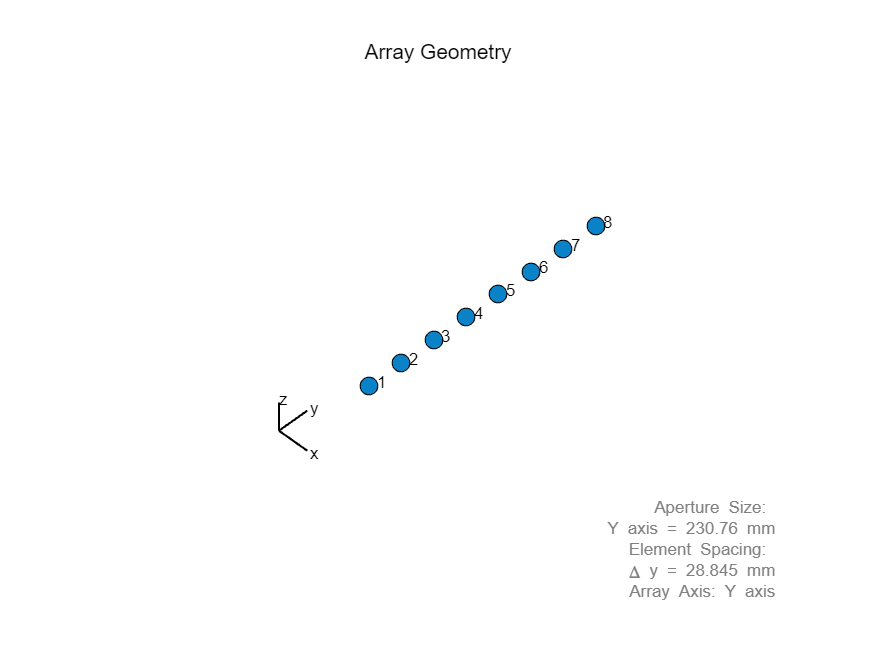

% N = getNumElements(ula); disp(N);
viewArray(ula,'ShowIndex','All');

c = physconst('LightSpeed');
f_c = 2.4e9; % center frequency (Hz)
f_p = 2e6; % modulation frequency (Hz)

Second, we define the incident signals for K=2 sources. 

Simulate the array output for two incident signals. Both signals are incident from 90° in azimuth. Their elevation angles are 73° and 68° respectively. In this example, we assume that these two directions are unknown and need to be estimated. Simulate the baseband received signal at the array demodulated from an operating frequency of 300 MHz.

fc = 300e6;                               % Operating frequency
fs = 8192;                                % Sampling frequency
lambda = physconst('LightSpeed')/fc;      % Wavelength
pos = getElementPosition(ula)/lambda;     % Element position in wavelengths
ang1 = [90;73]; ang2 = [90;68];           % Direction of the signals
angs = [ang1 ang2];
Nsamp = 1024;                             % Number of snapshots
noisePwr = 0.01;                          % Noise power

rs = rng(2012);                           % Set random number generator
signal = sensorsig(pos,Nsamp,angs,noisePwr);

In MATLAB, we define the simulated sources with the elevation and azimuth. 

The incident angle is referred to in MATLAB examples as the "broadside angle".

Because a ULA is symmetric around its axis, a DOA algorithm cannot uniquely determine azimuth and elevation. Therefore, the results returned by these high-resolution DOA estimators are in the form of broadside angles. An illustration of broadside angles can be found in the following figure.

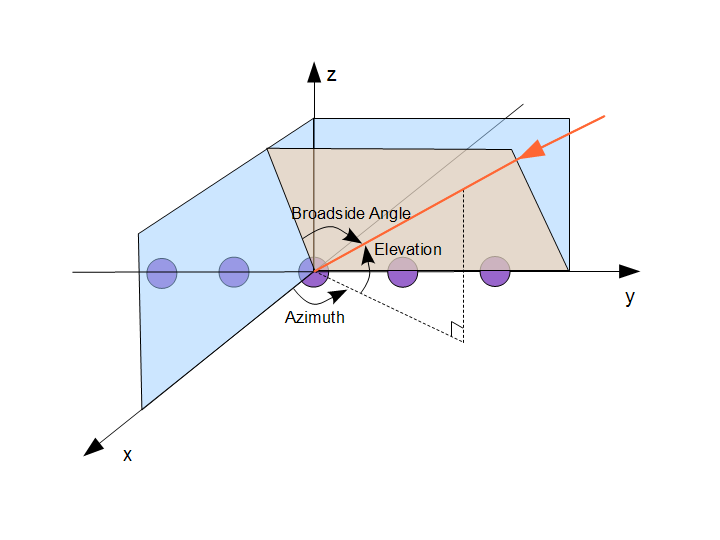

Calculate the broadside angles corresponding to the two incident angles.

ang_true = az2broadside(angs(1,:),angs(2,:))

ang_true =    17.0000   22.0000


### DoA with ESPRIT

We can also use an ESPRIT DOA estimator. As in the case of root-MUSIC, set the ForwardBackwardAveraging property to true. This algorithm is also called unitary ESPRIT.

espritangle = phased.ESPRITEstimator('SensorArray',ula,...
             'OperatingFrequency',fc,'ForwardBackwardAveraging',true,...
             'NumSignalsSource','Property','NumSignals',2)

espritangle =   phased.ESPRITEstimator with properties:

                 SensorArray: [1×1 phased.ULA]
            PropagationSpeed: 299792458
          OperatingFrequency: 300000000
            NumSignalsSource: 'Property'
                  NumSignals: 2
            SpatialSmoothing: 0
                      Method: 'TLS'
    ForwardBackwardAveraging: true
                RowWeighting: 1


ang = espritangle(signal)

ang =    21.9915   16.9871


### DoA with MUSIC

Finally, use the MUSIC DOA estimator. MUSIC also supports forward-backward averaging. Unlike ESPRIT and root-MUSIC, MUSIC computes a spatial spectrum for specified broadside scan angles. Directions of arrival correspond to peaks in the MUSIC spatial spectrum.

musicangle = phased.MUSICEstimator('SensorArray',ula,...
             'OperatingFrequency',fc,'ForwardBackwardAveraging',true,...
             'NumSignalsSource','Property','NumSignals',2,...
             'DOAOutputPort',true)

musicangle =   phased.MUSICEstimator with properties:

                 SensorArray: [1×1 phased.ULA]
            PropagationSpeed: 299792458
          OperatingFrequency: 300000000
    ForwardBackwardAveraging: true
            SpatialSmoothing: 0
                  ScanAngles: [-90 -89 -88 -87 -86 -85 -84 -83 -82 -81 -80 -79 -78 -77 -76 -75 -74 -73 -72 -71 -70 -69 -68 -67 -66 -65 -64 -63 -62 -61 -60 -59 -58 -57 -56 -55 -54 -53 -52 -51 -50 -49 -48 -47 -46 -45 -44 -43 -42 -41 -40 -39 -38 -37 -36 … ]
               DOAOutputPort: true
                  NumSignals: 2
            NumSignalsSource: 'Property'


[~,ang] = musicangle(signal) 

ang =     22    17


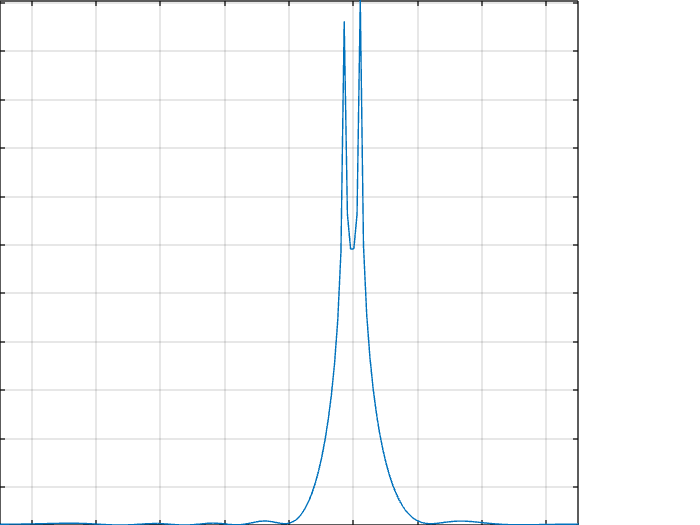

plotSpectrum(musicangle)

Directions of arrival for MUSIC are limited to the scan angles in the `ScanAngles` property. Because the true directions of arrival in this example coincide with the search angles in `ScanAngles`, MUSIC provides precise DOA angle estimates. In practice, root-MUSIC provides superior resolution to MUSIC. However, the MUSIC algorithm can also be used for DOA estimation in both azimuth and elevation using a 2-D array. See [Direction of Arrival Estimation with Beamscan, MVDR, and MUSIC](docid:phased_ug.example-ex62922668).